## Frequency Analysis

#### General parameters 

These are the same 'options' used for the filtering and segmentation

clearvars

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

addpath('./FreqFeatures')


data = importdata("../physionet.org/segmented_data/3000063_0016-0024.txt");

[f, fftABP] = singlesidedFFT(data(:,1), data(:,2));

[~, fftPPG] = singlesidedFFT(data(:,1), data(:,3));

df = mean(diff(f))

df = 0.0344

Fs = df*(length(f)*2)

Fs = 125.0000

dT = 1/Fs

dT = 0.0080

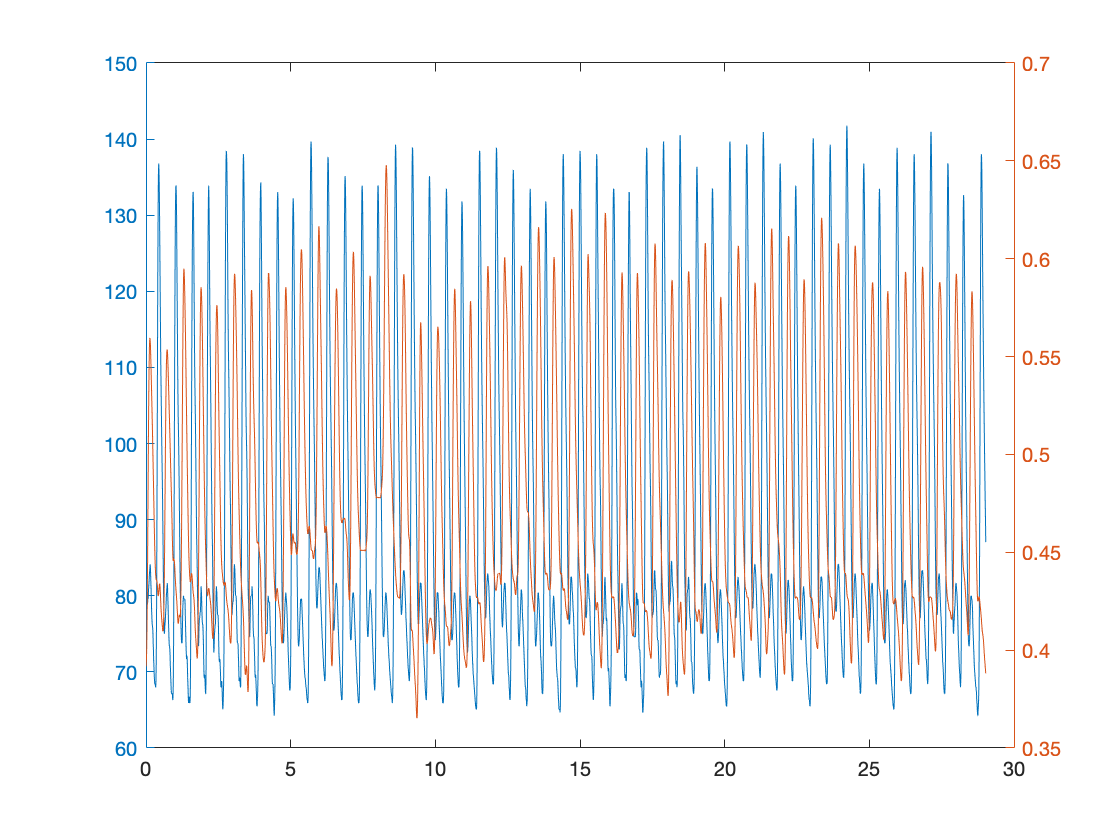



figure;
yyaxis left
plot(data(:,1), data(:,2))
hold on;
yyaxis right
plot(data(:,1), data(:,3))
hold off

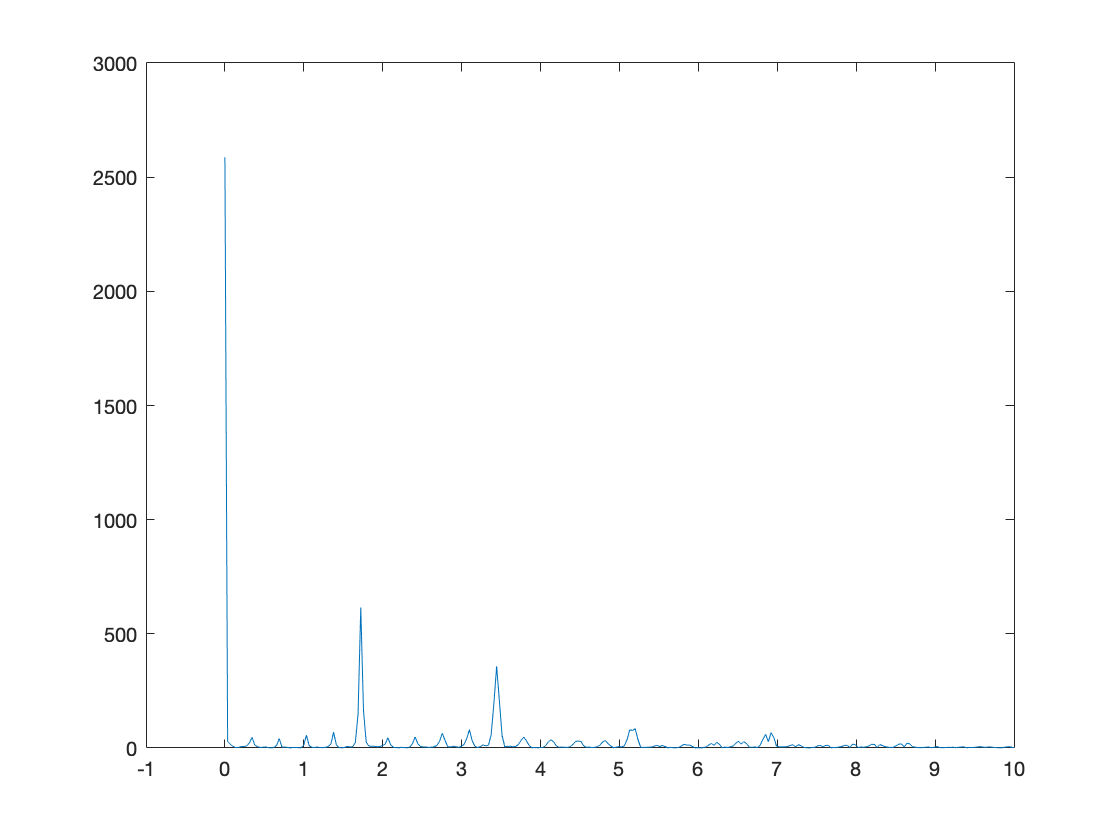


figure;
plot(f, abs(fftABP))
xlim([-1 10])

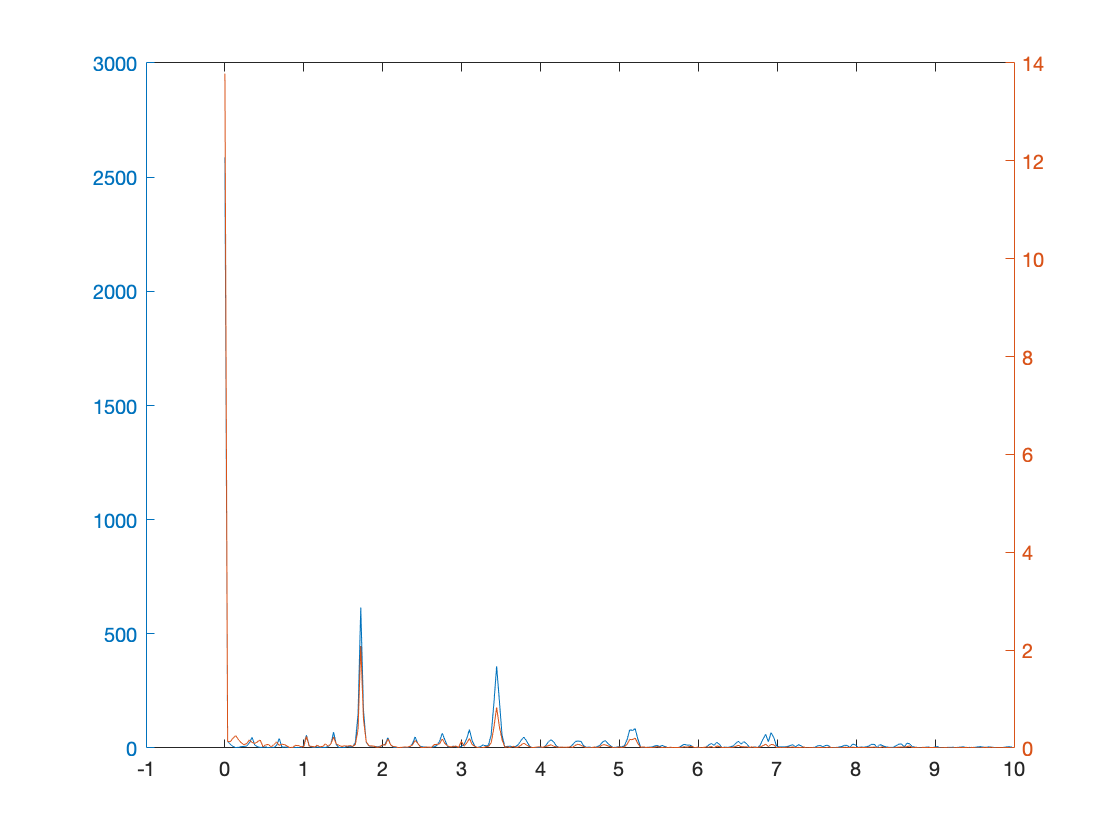


figure;
yyaxis("left")
plot(f, abs(fftABP))
xlim([-1 10])
hold on
yyaxis("right")
plot(f, abs(fftPPG))
xlim([-1 10])
hold off

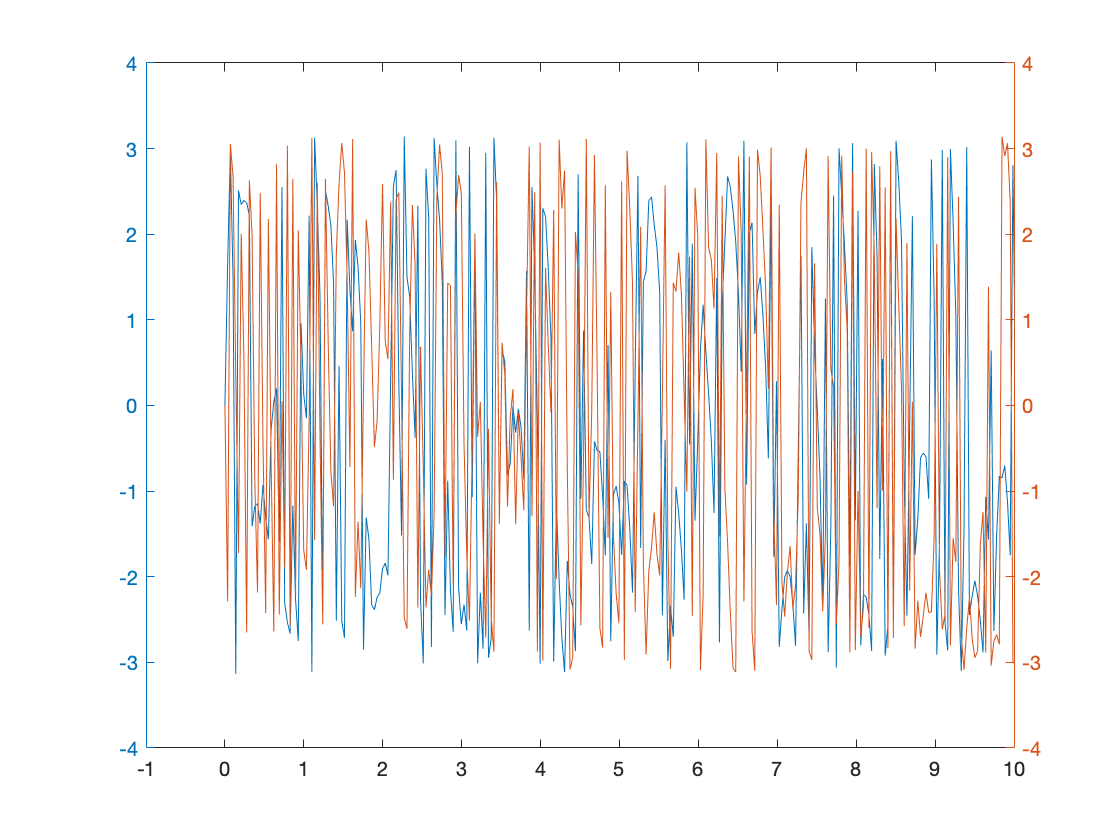


figure;
yyaxis("left")
plot(f, angle(fftABP))
xlim([-1 10])
hold on
yyaxis("right")
plot(f, angle(fftPPG))
xlim([-1 10])
hold off

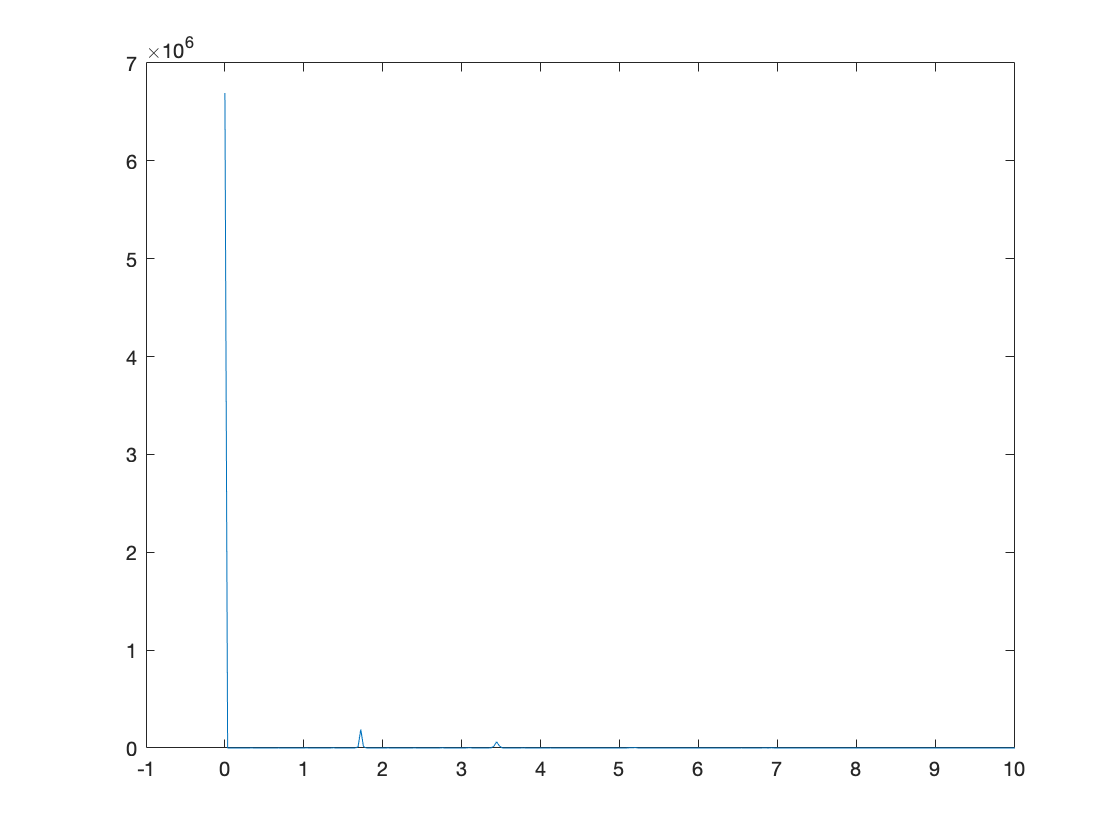


psdABP = (abs(fftABP)).^2;
psdABP(2:end) = psdABP(2:end)/2;

psdPPG = (abs(fftPPG)).^2;
psdPPG(2:end) = psdPPG(2:end)/2;

 
figure;
plot(f, abs(psdABP))
xlim([-1 10])

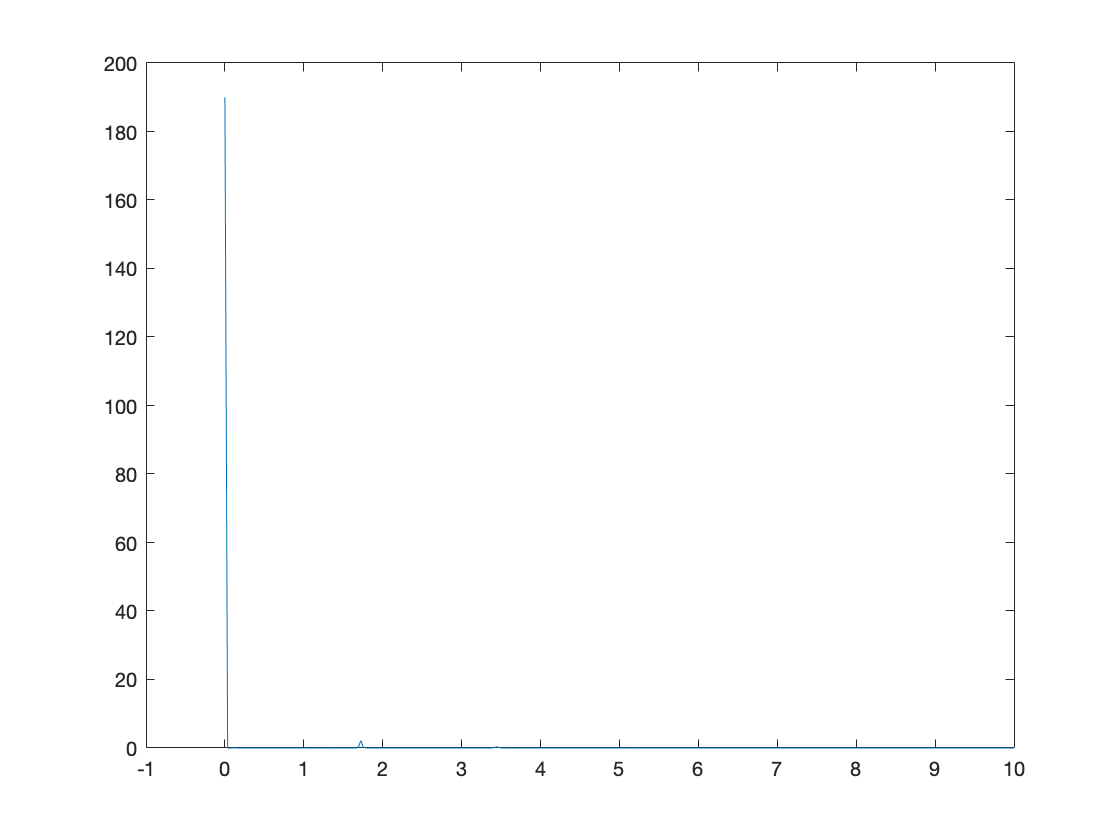

figure;
plot(f, abs(psdPPG))
xlim([-1 10])

### Method 1

Extract DC and 100 (or X) most powerful frequencies and reconstruct the ABP using these frequencies.

% Extract DC + 100 most powerful freqs
% 
% maximaIndices = [1; extractMaxFreqSpectrum(abs(psdABP), 16, 0)]
% 
% recon_fftABP = zeros(size(fftABP));
% recon_fftABP(maximaIndices) = fftABP(maximaIndices);
% 
% [recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);
% 
% plot(f, abs(recon_fftABP))
% xlim([-1 10])
% plot(recon_time, recon_ABP)
% title("Recon ABP")
% plot(data(:,1), data(:,2))
% title("ABP")


### Method 2

Determine which frequency components make up 99% (or X %) of the signal, and reconstruct the ABP using these frequency components.

disp("Method 2")

Method 2


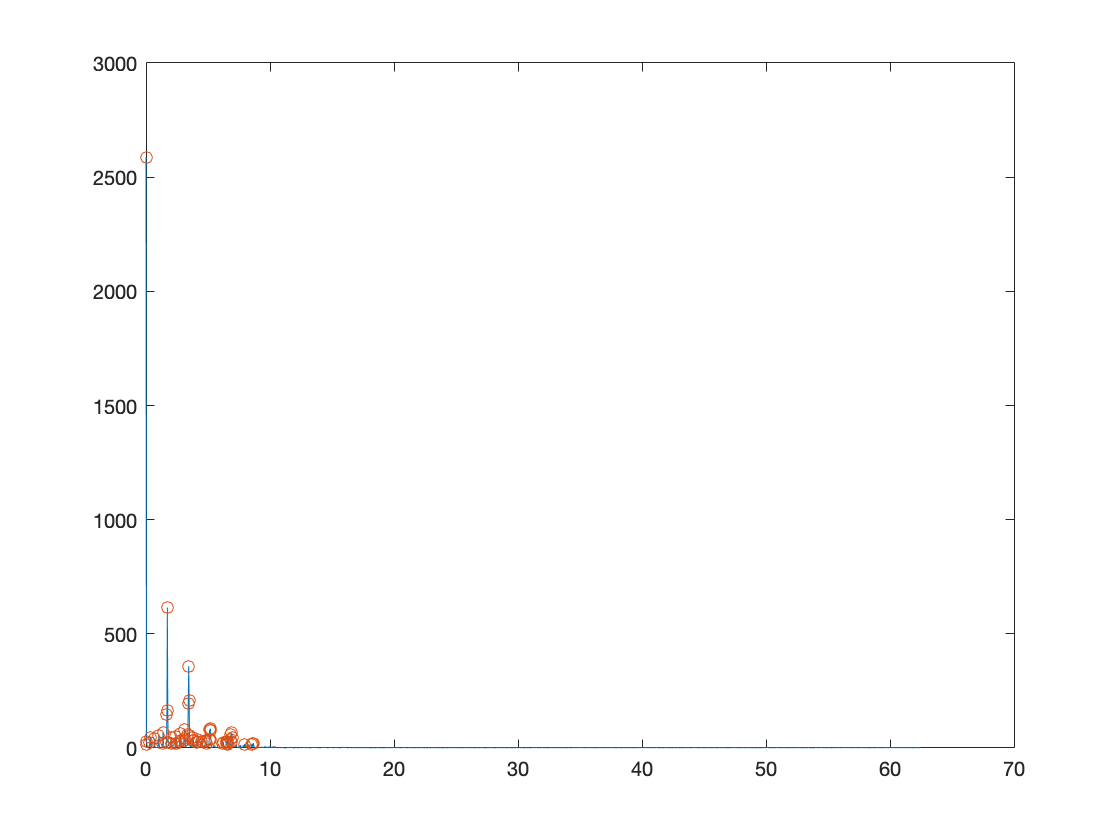

% get 99.9% of power components
maximaIndices = getPowerContributors(psdABP, 99.9, 0);

recon_fftABP = zeros(size(fftABP));
recon_fftABP(maximaIndices) = fftABP(maximaIndices);

[recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);

recon_fftABP2 = recon_fftABP;

plot(f, abs(fftABP));
hold on;
scatter(f(maximaIndices), abs(fftABP(maximaIndices)))
hold off;

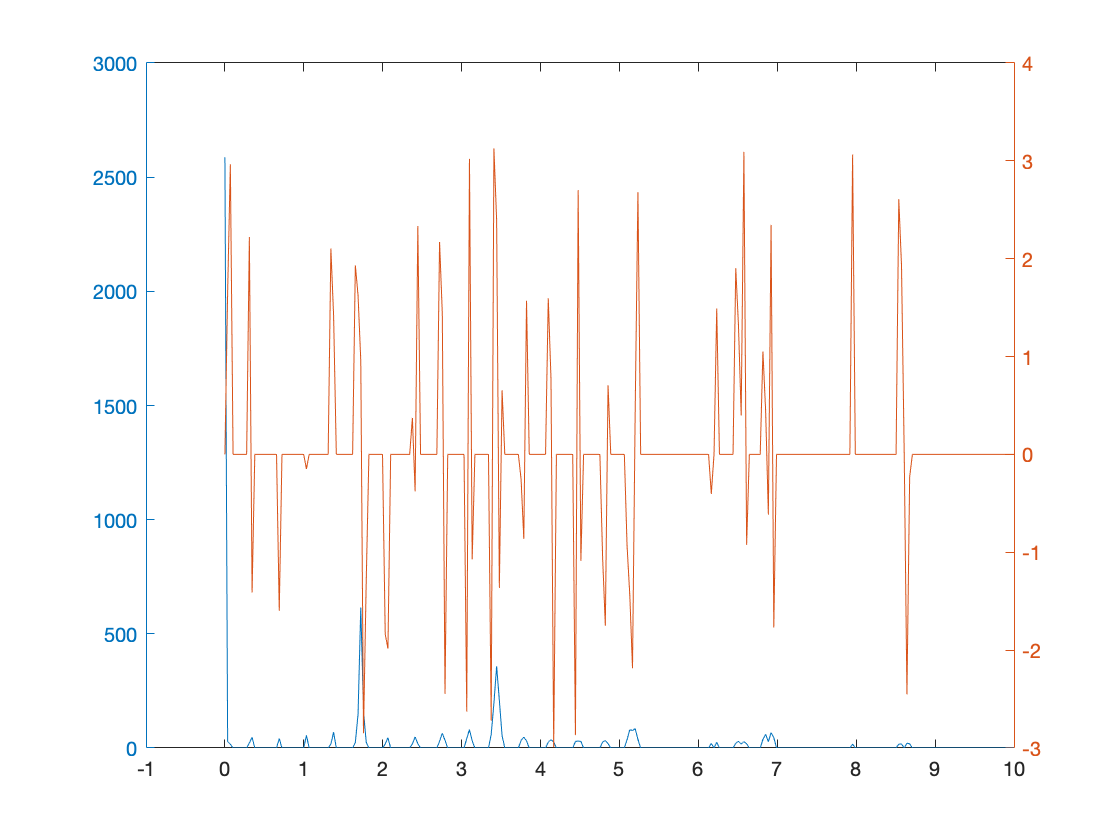


recon_time(length(data)+1:end) = [];
recon_ABP(length(data)+1:end) = [];

figure;
yyaxis left
plot(f, abs(recon_fftABP))
hold on
xlim([-1 10])
yyaxis right
plot(f, angle(recon_fftABP))
hold off

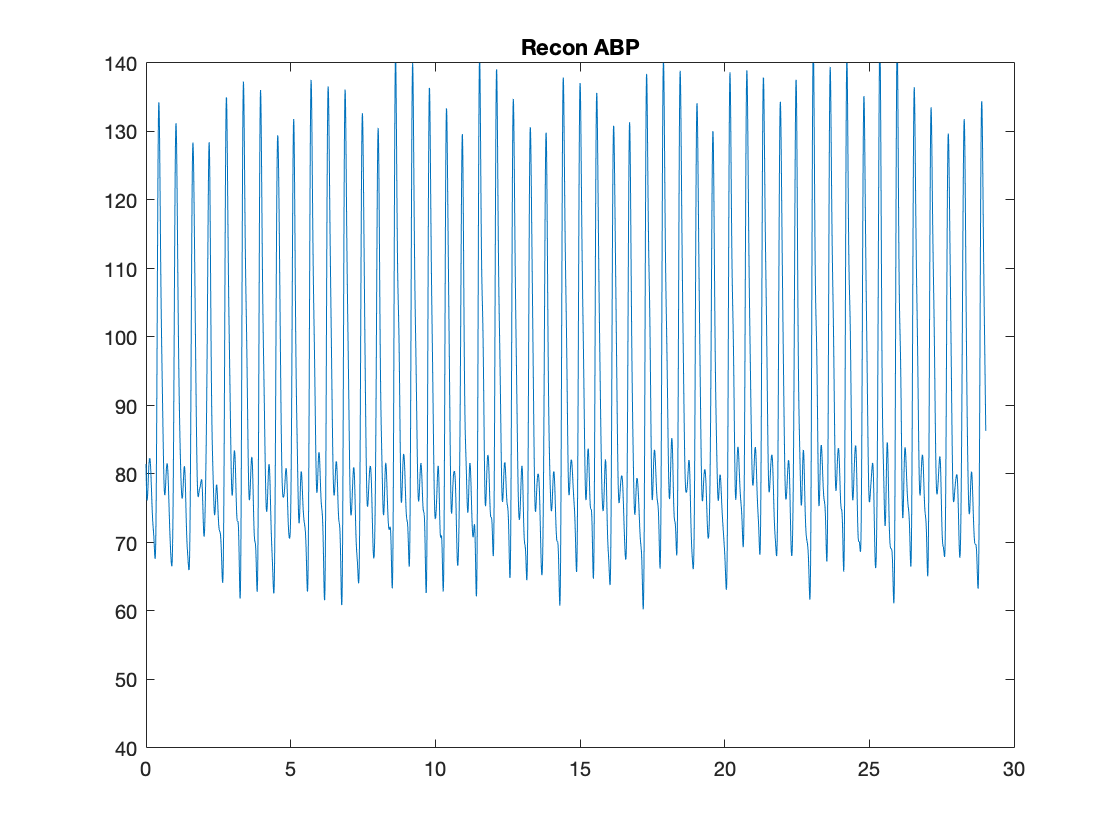


figure;
plot(recon_time, recon_ABP)
ylim([40 140])
%xlim([10 20])
title("Recon ABP")

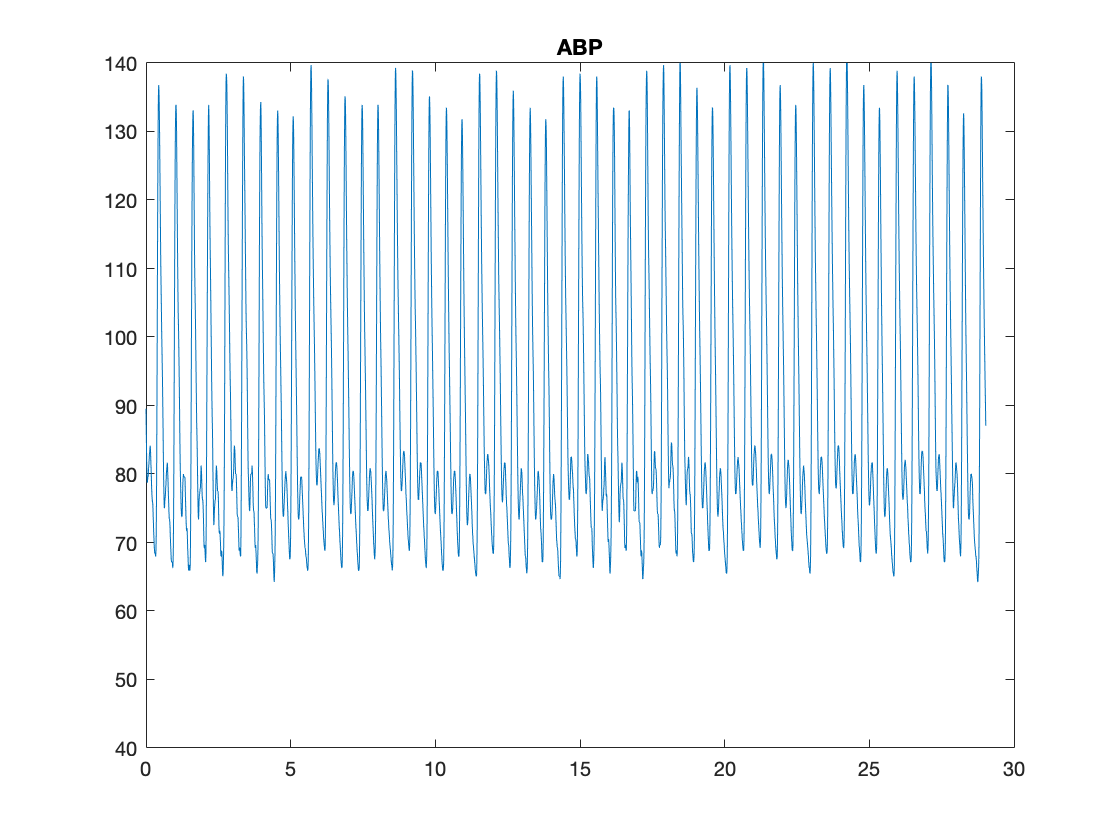

plot(data(:,1), data(:,2))
ylim([40 140])
%xlim([10 20])
title("ABP")


recon_ABP2 = recon_ABP;

cost_sse = sum((recon_ABP - data(:,2)).^2)

cost_sse = 2.2921e+04

cost_mse = cost_sse/length(data)

cost_mse = 6.3159

### Method 3

Divide the frequency spectrum into a number of "frequency bins", for example, 1 Hz wide. The most significant frequencies within each of these bins are then extracted and used to reconstruct the ABP waveform.

% use frequency bins
% indices = getMaxFreqsInBins(f, abs(fftABP), 3, 1, 10);
% 
% recon_fftABP = zeros(size(fftABP));
% recon_fftABP(indices) = fftABP(indices);
% 
% plot(f, abs(fftABP));
% hold on;
% scatter(f(indices), abs(fftABP(indices)))
% hold off;
% 
% [recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);
% 
% recon_time(length(data)+1:end) = [];
% recon_ABP(length(data)+1:end) = [];
% 
% plot(f, abs(recon_fftABP))
% xlim([-1 10])
% 
% %recon_ABP = lowpass(recon_ABP, 8, 125);
% 
% plot(recon_time, recon_ABP)
% ylim([40 120])
% %xlim([10 20])
% plot(data(:,1), data(:,2))
% ylim([40 120])
% %xlim([10 20])
% 
% cost_sse = sum((recon_ABP - data(:,2)).^2)
% cost_mse = cost_sse/length(data)


### Using a transfer function approach

Seems whack

% tol = 1e-2;
% 
% fftABP(abs(fftABP) < tol) = 0;
% 
% fftPPG(abs(fftPPG) < tol) = 0;
% 
% transFunc = fftABP./fftPPG;
% 
% plot(f, abs(transFunc))
% title("Transfer Function")
% 
% [tf_time, tf] = singlesidedIFFT(f, transFunc);
% plot(tf_time, tf)

### Applying sinc pulses

% disp("Method 2 + Sinc pulses")
% % get 99.9% of power components
% peakIndices = getPowerContributors(psdABP, 99.3, 1);
% 
% df = mean(diff(f));
% 
% halfWidth = df*2;
% 
% fSinc = (-4:4)*df;
% 
% sincPulse = abs(sinc(fSinc/halfWidth));
% figure;
% plot(fSinc, sincPulse);
% 
% recon_fftABP = zeros(size(fftABP));
% for p = 1:length(peakIndices)
%     if peakIndices(p) == 1
%         start = peakIndices(p)
%         recon_fftABP(start:start+4) = abs(fftABP(peakIndices(p)))*sincPulse(5:9);
%     else
%         start = peakIndices(p)-4
%         recon_fftABP(start:start+8) = abs(fftABP(peakIndices(p)))*sincPulse;
%     end
% end
% 
% plot(f, recon_fftABP);
% hold on;
% plot(f, abs(fftABP));
% hold off;
% xlim([-1 8])

%[recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);

### Applying Gaussian pulses

gaussianPulse = @(x,mean, stddev) exp(-(((x-mean).^2)/(2*stddev.^2)));

%peakIndices = getPowerContributors(psdABP, 99.3, 1);

[~,peakIndices] = findpeaks(psdABP, 'NPeaks', 6, "SortStr", "descend");

peakIndices = [1;peakIndices];

df = mean(diff(f));

gaussWidth = 0.0378

gaussWidth = 0.0378

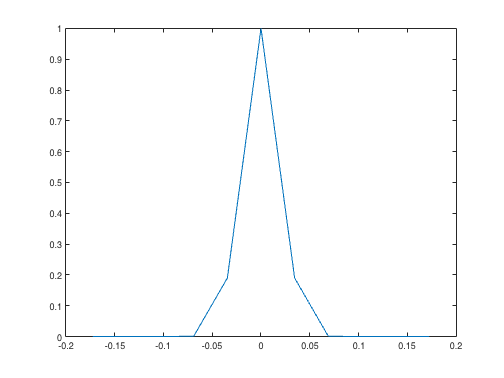

stdDev = gaussWidth/2;

freqGauss = (-5:5)*df;

pulseGauss = gaussianPulse(freqGauss, 0, stdDev)';

plot(freqGauss, pulseGauss);        

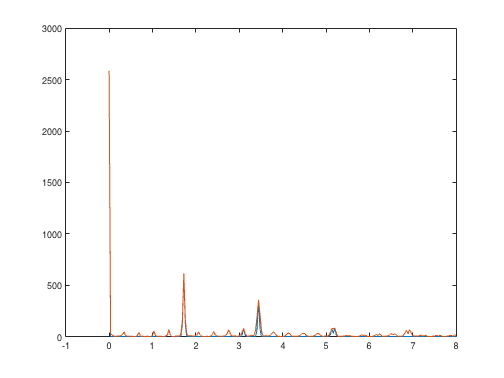


recon_fftABP = zeros(size(fftABP));
for p = 1:length(peakIndices)
    if peakIndices(p) == 1
        recon_fftABP(1) = fftABP(1);
    else    
        gpStart = peakIndices(p)-5;
        gpEnd = gpStart+10;
        gpS = max(1,gpStart);
        gpE= min(gpEnd,length(f));
        
        recon_fftABP(gpS:gpE) = recon_fftABP(gpS:gpE) +  abs(fftABP(peakIndices(p)))*pulseGauss(gpS-gpStart+1:end-(gpE-gpEnd));
    end
end

peakIndices = peakIndices(2:end);

% phases = zeros(size(fftABP)); 
% phases(peakIndices) = angle(fftABP(peakIndices));
% phases(peakIndices-1) = angle(fftABP(peakIndices-1));
% phases(peakIndices+1) = angle(fftABP(peakIndices+1));

recon_fftABP = abs(recon_fftABP).*exp(i.*angle(fftABP));

plot(f, abs(recon_fftABP));
hold on;
plot(f, abs(fftABP));
hold off;
xlim([-1 8])

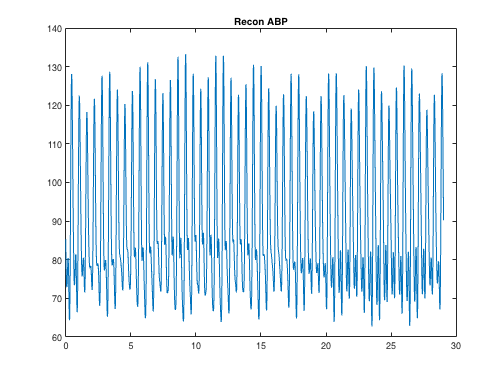



[recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);

recon_time(length(data)+1:end) = [];
recon_ABP(length(data)+1:end) = [];

figure;
plot(recon_time, recon_ABP)
title("Recon ABP")

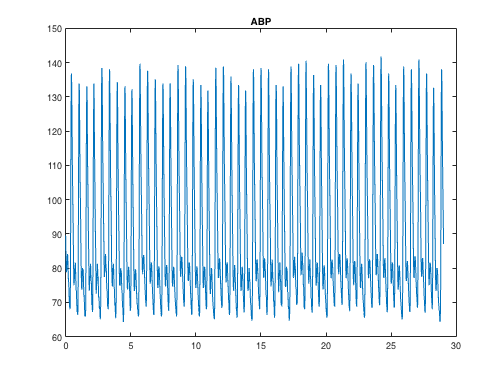

plot(data(:,1), data(:,2))
title("ABP")

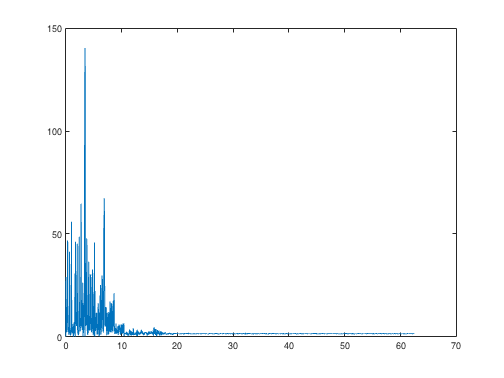


diff_fft = fftABP - recon_fftABP;
plot(f, abs(diff_fft))



cost_sse = sum((recon_ABP - data(:,2)).^2);
cost_mse = cost_sse/length(data)

cost_mse = 65.7493

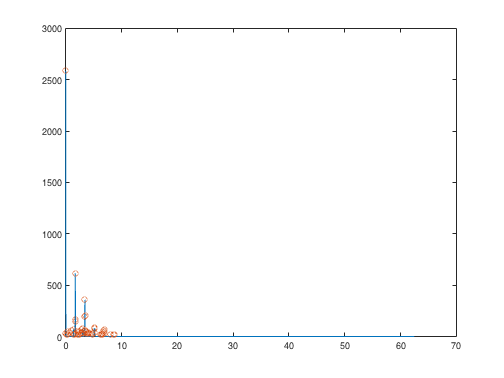


plot(f, abs(recon_fftABP));
hold on;
scatter(f(maximaIndices), abs(fftABP(maximaIndices)))
hold off;

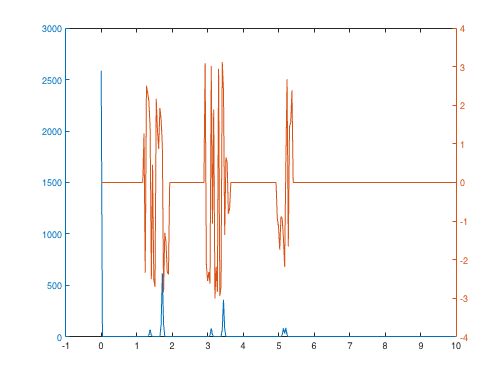


figure;
yyaxis left
plot(f, abs(recon_fftABP))
hold on
xlim([-1 10])
yyaxis right
plot(f, angle(recon_fftABP))
hold off

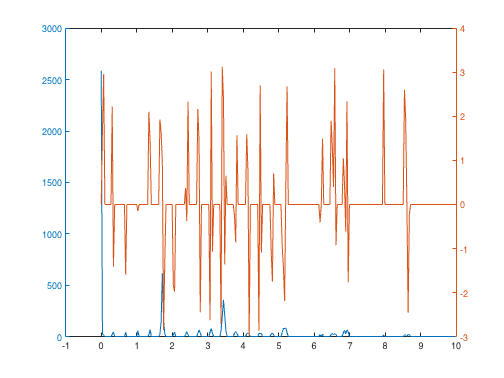


figure;
yyaxis left
plot(f, abs(recon_fftABP2))
hold on
xlim([-1 10])
yyaxis right
plot(f, angle(recon_fftABP2))
hold off

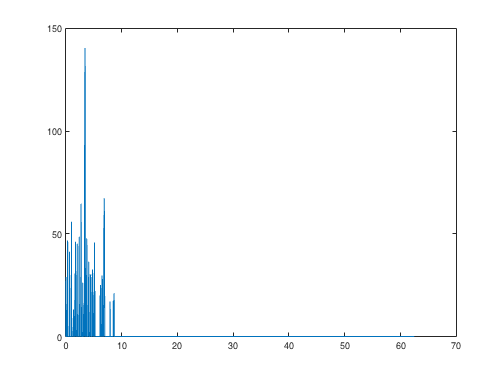


figure;
plot(f, abs(recon_fftABP2 - recon_fftABP))

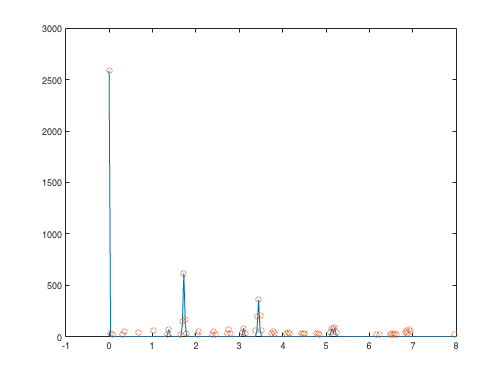


plot(f, abs(recon_fftABP));
hold on;
scatter(f(maximaIndices), abs(recon_fftABP2(maximaIndices)));
hold off;
xlim([-1 8])

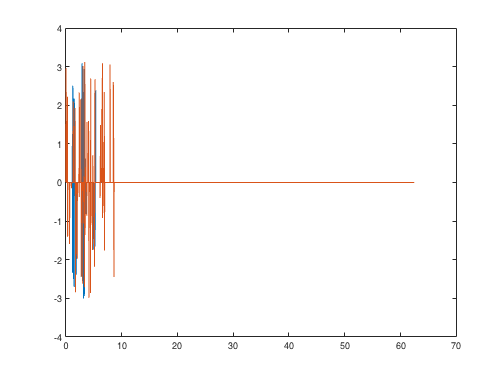


figure;
plot(f, angle(recon_fftABP));
hold on;
plot(f, angle(recon_fftABP2));
hold off;